deviancy = 'C:\Users\maran\MATLAB Drive\thesisFinal\testTrackResults\oCRdev.csv'

deviancy = 'C:\Users\maran\MATLAB Drive\thesisFinal\testTrackResults\oCRdev.csv'


M = csvread(deviancy)

M =          0  841.0000
    0.2000  841.0000
    0.4000  841.0000
    0.6000  841.0000
    0.8000         0
    1.0000   58.0000
    1.2000   58.0000
    1.4000         0
    1.6000         0
    1.8000         0



x = M(:,1)

x =          0
    0.2000
    0.4000
    0.6000
    0.8000
    1.0000
    1.2000
    1.4000
    1.6000
    1.8000


y = M(:,2)

y =    841
   841
   841
   841
     0
    58
    58
     0
     0
     0


xMax = x(10:end,:)

xMax =     1.8000
    2.0000
    2.2000
    2.4000
    2.6000
    2.8000
    3.0000
    3.2000
    3.4000
    3.6000


yMax = y(10:end,:)

yMax =      0
     0
     0
     0
     8
    10
    11
    21
    29
    31



segmentOne = y(25:300,:)

segmentOne =     42
    44
    46
    48
    52
    56
    58
    58
    58
    58


segmentTwo = y(360:500,:)

segmentTwo =     57
    59
    59
    57
    57
    57
    59
    57
    61
    63


%segmentThree = y(375:445,:)
%segmentFour = y(365:430,:)

overall = max(yMax)

overall = 252

sOne = max(segmentOne)

sOne = 252

sTwo = max(segmentTwo)

sTwo = 225

%sThr = max(segmentThree)
%sFo = max(segmentFour)
Maximum = [overall; sOne; sTwo]

Maximum =    252
   252
   225


Maximum = round(Maximum,3, 'significant')

Maximum =    252
   252
   225



overMean = rms(y)

overMean = 149.0063

smOne = rms(segmentOne)

smOne = 127.9219

smTwo = rms(segmentTwo)

smTwo = 128.8334

%smThr = rms(segmentThree)
%smFo = rms(segmentFour)
Average = [overMean; smOne; smTwo]

Average =   149.0063
  127.9219
  128.8334


Average = round(Average,3, 'significant')

Average =    149
   128
   129



overSTD = std(overall)

overSTD = 0

ssmOne = std(segmentOne)

ssmOne = 65.6377

ssmTwo = std(segmentTwo)

ssmTwo = 66.3637

%ssThr = std(segmentThree)
%ssmFo = std(segmentFour)
StandardDeviation = [overSTD; ssmOne; ssmTwo]

StandardDeviation =          0
   65.6377
   66.3637


StandardDeviation = round(StandardDeviation,3, 'significant')

StandardDeviation =          0
   65.6000
   66.4000



Segments = {'Overall';'Segment 1';'Segment 2'}

Segments = 3×1 cell array
    {'Overall'  }
    {'Segment 1'}
    {'Segment 2'}


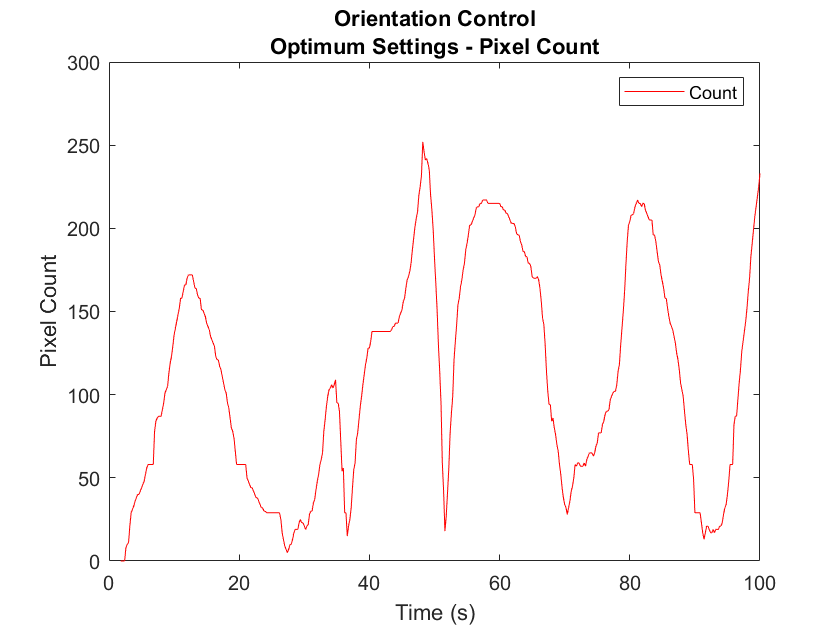


plot(xMax,yMax,'r');
xlabel('Time (s)');
ylabel('Pixel Count');
title({'Orientation Control'; 'Optimum Settings - Pixel Count'})
legend({'Count'},'Location','northeast')


SEM = StandardDeviation/sqrt(length(segmentOne))

SEM =          0
    3.9487
    3.9968


SEM = round(SEM,3, 'significant')

SEM =          0
    3.9500
    4.0000



T = table(Segments,Maximum, Average,StandardDeviation, SEM)

T = 3×5 table
      Segments       Maximum    Average    StandardDeviation    SEM 
    _____________    _______    _______    _________________    ____

    {'Overall'  }      252        149               0              0
    {'Segment 1'}      252        128            65.6           3.95
    {'Segment 2'}      225        129            66.4              4


disp(T)

      Segments       Maximum    Average    StandardDeviation    SEM 
    _____________    _______    _______    _________________    ____

    {'Overall'  }      252        149               0              0
    {'Segment 1'}      252        128            65.6           3.95
    {'Segment 2'}      225        129            66.4              4



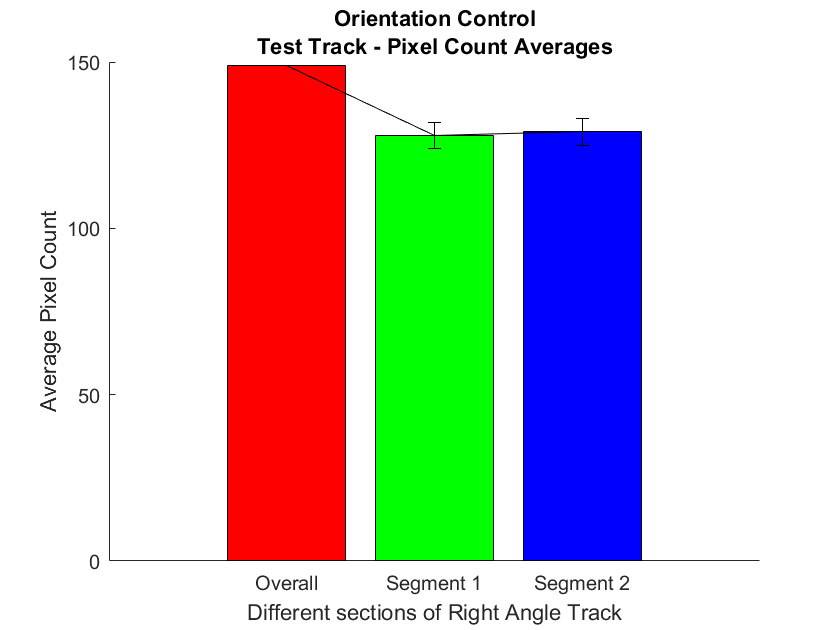

fHand = figure;
aHand = axes('parent', fHand);
hold(aHand, 'on')
colors = hsv(numel(Average));
for i = 1:numel(Average)
    b = bar(i, Average(i), 'parent', aHand, 'facecolor', colors(i,:));
end
set(gca, 'XTick', 1:numel(Average), 'XTickLabel', {'Overall';'Segment 1';'Segment 2';'Segment 3';'Segment 4'})
errorbar(Average, SEM,'k');
title({'Orientation Control'; 'Test Track - Pixel Count Averages'})
xlabel('Different sections of Right Angle Track')
ylabel('Average Pixel Count')